# Homework 2 - Image Processing

clc;clear all;close all;
s = settings; %Change font size and font name
s.matlab.fonts.editor.normal.Size.PersonalValue = 12;
s.matlab.fonts.editor.normal.Name.PersonalValue = 'Times New Roman';
clear s

## Question 1

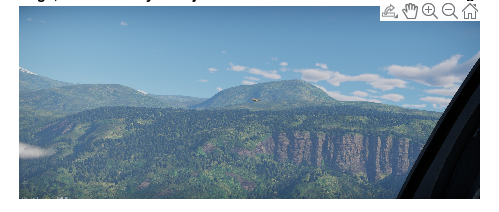

im1 = imread('shot 2024.07.08 11.57.30.jpg');
figure();
imshow(im1)
title('First image, an IAF A4 Skyhawk jet in a mountainous environment with vegetation')

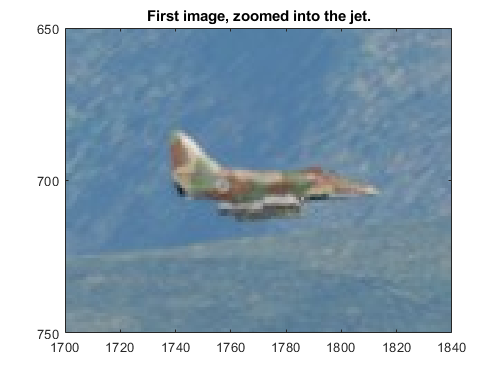


jetLocx = [1700 1840];
jetLocy = [650 750];

figure();
image(im1)
xlim(jetLocx)
ylim(jetLocy)
title('First image, zoomed into the jet.')

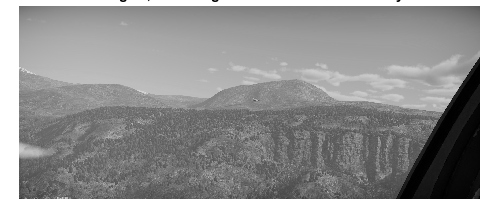


im1 = im1(:, :, 2);
figure();
imshow(im1)
title('Image 1, with the green channel extracted only')

## Question 2

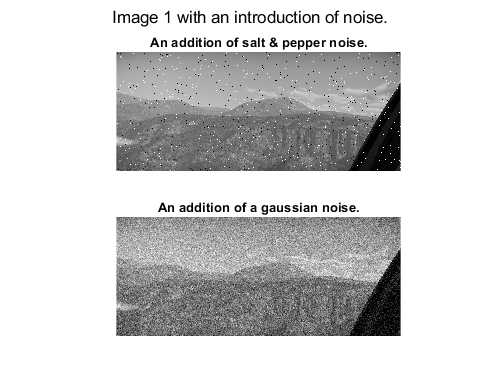

im1SaltNoise = imnoise (im1, 'salt & pepper', 0.02);
figure();
subplot(2,1,1)
imshow(im1SaltNoise)
title('An addition of salt & pepper noise.')

im1GausNoise = imnoise(im1, "gaussian", 0.01);
subplot(2,1,2)
imshow(im1GausNoise)
title('An addition of a gaussian noise.')

sgtitle('Image 1 with an introduction of noise.')

## Question 3

First, implementation of a kernel sized 3x5:

help medianFilter

  Median filter kernel.
  medianFilter(imag, x, y) where imag is the image matrix, x is the
  horizontal dimension of the kernel and y is the vertical dimension of
  the kernel.
  Kernel dimensions must be odd numbers.




imMedian1 = medianFilter(im1SaltNoise, 3, 5);
figure();
subplot(2,2,1)
imshow(imMedian1)
title('Salt & pepper noise with a 3x5 kernel.')

Next, using a kernel sized 5x3:

imMedian2 = medianFilter(im1SaltNoise, 5, 3);
subplot(2,2,2)
imshow(imMedian2)
title('Salt & pepper noise with a 5x3 kernel.')

The same process for gaussian noise:

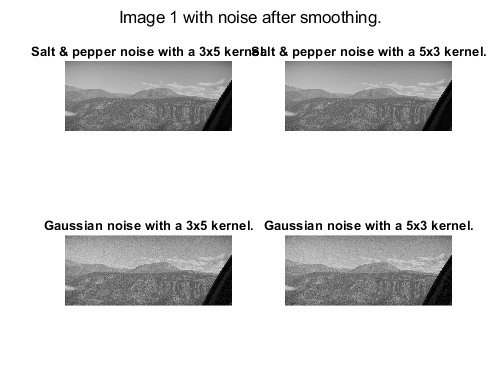

imMedian3 = medianFilter(im1GausNoise, 3, 5);
subplot(2,2,3)
imshow(imMedian3)
title('Gaussian noise with a 3x5 kernel.')

imMedian4 = medianFilter(im1GausNoise, 5, 3);
subplot(2,2,4)
imshow(imMedian4)
title('Gaussian noise with a 5x3 kernel.')

sgtitle('Image 1 with noise after smoothing.')

After implementing the smoothing, we can see that it works way better on an image with salt & pepper style noise.

The difference in the images, comparing a 3x5 kernel to a 5x3 kernel:

isequal(imMedian1, imMedian2)

ans = logical
   0


isequal(imMedian3, imMedian4)

ans = logical
   0


We can see that the images are not equal, we have different value for the pixels. Let's calculate the difference:

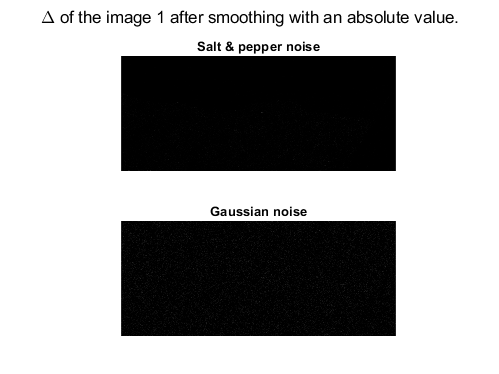

deltaSalt = abs(imMedian1 - imMedian2);
deltaGaus = abs(imMedian3 - imMedian4);

figure();
subplot(2,1,1)
imshow(deltaSalt)
title('Salt & pepper noise')
subplot(2,1,2)
imshow(deltaGaus)
title('Gaussian noise')

sgtitle('\Delta of the image 1 after smoothing with an absolute value.')